## Exercise 64

Questo esercizio ha come obiettivo quello di focalizzare la procedura di identificazione su una banda di frequenza selezionata dall'utente.

**In questo esercizio si dimostrerà che anche con un modello troppo semplice è possibile focalizzare il modello su una banda di frequenza selezionata dall'utente: non è più necessario che il modello si adatti ai dati in ogni punto, ma solo nella banda di frequenza selezionata dall'utente dove si desidera una buona corrispondenza.** 

In questo esercizio è stata sceltao la banda di frequenze intorno alla prima risonanza del sistema. 

Esistono due possibilità per ottenere questa focalizzazione:

- **Nel dominio del tempo**, i segnali misurati u0, y0 possono essere pre-filtrati. Ciò non influisce sulla relazione lineare tra i due segnali, ma modifica il modello stimato. 

- **Nel dominio della frequenza**, la focalizzazione si ottiene selezionando solo le frequenze nella funzione di costo che si trovano nella banda di frequenza di interesse. 

**Questo esercizio illustrerà solo la procedura nel dominio del tempo.**

Si procederà, quindi, a focalizzare il modello sulla banda di frequenza selezionata dall'utente [0,04 0,08] (f_s = 1) utilizzando un prefiltro. 

### Definizione delle variabili di input

clear
clc 

N = 5000;                                 % number of datapoints
NTrans = 1000;                            % eliminate the transients of the simulation
StdNoise = 0.;                            % standard deviation of the disturbing noise put to zero
Lines = floor([0.04*N:1:0.08*N]);         % DFT lines used for plotting

- La variabile `N` rappresenta il numero di campioni nel segnale, in questo caso, `N` è impostato a 5000.

- La variabile `NTrans` rappresenta il numero di campioni da eliminare come transitori nella simulazione. Questi campioni iniziali vengono scartati per evitare i transitori degli stati.

- La variabile `StdNoise` rappresenta la deviazione standard del rumore aggiunto al segnale, in questo caso, è impostato a zero, quindi non viene aggiunto rumore.

- La variabile `Lines` rappresenta le frequenze (linee DFT) utilizzate per il tracciamento del grafico. Viene creato un vettore di frequenze a partire da 0,04*N fino a 0,08*N, con passo 1.

### Progetto del Filtro di generazione del segnale di Uscita

[b0, a0] = cheby1(5, 5, 2*0.1);          % system G0

Questa riga utilizza la funzione `cheby1` per progettare un filtro di Chebyshev di tipo I. 

I parametri specificati sono: 

- ordine del filtro `5;`

- attenuazione in dB `5`

- frequenza di taglio normalizzata `2*0.1`. 

I coefficienti `b0` e `a0` rappresentano i coefficienti del filtro di sistema `G0`.

### Progetto del Filtro di generazione del segnale di Ingresso

[bGen, aGen] = cheby1(5, 1, 2*0.15*3);   % generation filter

Questa riga utilizza nuovamente la funzione `cheby1` per progettare un filtro di Chebyshev di tipo I. 

I parametri specificati sono: 

- ordine del filtro `5;`

- attenuazione in dB `1;`

- frequenza di taglio normalizzata `2*0.15*3`. 

I coefficienti `bGen` e `aGen` rappresentano i coefficienti del filtro di generazione utilizzato per generare il segnale di ingresso.

### Generazione del Segnale di Ingresso - Chebyshev di Tipo I

u0 = filter(bGen, aGen, randn(N+NTrans, 1));         % input signal

Questa riga genera il segnale di ingresso `u0` filtrando il rumore bianco gaussiano (`randn(N+NTrans, 1)`) con il filtro di generazione `bGen` e `aGen`.

Ad esempio, supponiamo che `N = 10` e `NTrans = 5`. Il rumore bianco gaussiano generato casualmente potrebbe essere `[0.2; -0.5; 1.1; -0.8; 0.3; -0.1; 1.5; -1.2; -0.9; 0.7]`. Se applichiamo il filtro di generazione a questo segnale, otterremo il segnale di ingresso `u0` filtrato.

### Generazione del Segnale di Uscita - Chebyshev di Tipo I

y = filter(b0, a0, u0) + StdNoise*randn(N+NTrans, 1);  % output signal

Questa riga genera il segnale di uscita `y` filtrando il segnale di ingresso `u0` con il filtro di sistema `b0` e `a0`. Viene quindi aggiunto rumore gaussiano con deviazione standard `StdNoise` (che è zero in questo caso).

Utilizzando l'esempio precedente per `u0`, se applichiamo il filtro di sistema `b0` e `a0`, otteniamo il segnale di uscita `y`:

% y = filter(b0, a0, u0) + StdNoise*randn(N+NTrans, 1);
% y = filter(b0, a0, u0) + 0 * randn(N+NTrans, 1);
% y = filter(b0, a0, u0);
% y = [-0.1337; 0.4006; -0.1527; -0.1252; -0.3137; -0.2592; 0.3934; -0.3789; -0.3212; -0.0773];

La seguente riga elimina i transitori della simulazione rimuovendo i primi `NTrans` campioni dai segnali `u0` e `y`. Questo assicura che i transitori iniziali non influenzino l'analisi successiva.

u0(1:NTrans) = []; y(1:NTrans) = [];                 % eliminate the simulation transients

### Progetto del Prefiltro -  Butterworth

[bf, af] = butter(5, [0.04, 0.08]*2);        % create prefilter

Questa riga utilizza la funzione `butter` per progettare un filtro Butterworth. 

I parametri specificati sono: 

- ordine del filtro `5`

- frequenza di taglio normalizzata `[0.04, 0.08]*2`. 

I coefficienti `bf` e `af` rappresentano i coefficienti del prefiltro.

### Prefiltraggio dei segnali di Ingresso e Uscita

u0f = filter(bf, af, u0);                   % prefilter the input
yf = filter(bf, af, y);                     % prefilter the output

Queste righe filtrano il segnale di ingresso `u0` e il segnale di uscita `y` con il prefiltro avente coefficienti `bf` e `af`. I risultati filtrati sono memorizzati rispettivamente nelle variabili `u0f` e `yf`.

### Stima del modello ARX

In questo caso la costruzione del modello ARX viene effettuata manualmente piuttosto che utilizzare il comando diretto di MatLab [`sys = arx(u,y,[na nb nk])`](https://it.mathworks.com/help/ident/ref/arx.html#d124e6541) .

na = 2;                                   % order of the estimated model with model errors
nb = 2;
n = max(na, nb) + 1;

Queste righe definiscono gli ordini dell'ARX (AutoRegressive with eXogenous input) modello stimato. L'ordine del termine AR (AutoRegressive) è `na`, l'ordine del termine X (eXogenous) è `nb`, e `n` è l'ordine totale del modello, che è determinato prendendo il massimo tra `na` e `nb` e aggiungendo 1.

yRHS = -yf(n+1:end);                      % right hand side of the equations

Questa riga definisce il lato destro delle equazioni per stimare il modello ARX. Il vettore `yRHS` è ottenuto prendendo i campioni di `yf` a partire dall'indice `n+1` fino alla fine, e viene negato.

K = [toeplitz(yf(n:end-1), yf(n:-1:n-na+1))   -toeplitz(u0f(n+1:end), u0f(n+1:-1:n+1-nb))];

Questa riga crea la matrice dei regressori `K` per il problema di stima ARX. Vengono utilizzate le matrici Toeplitz delle sequenze di `yf` e `u0f` per costruire i regressori AR e X. La matrice `K` è composta da due parti: la prima parte è la matrice AR (denominatore) e la seconda parte è la matrice X (numeratore).

Theta = K \ yRHS;                           % least squares solution K * Theta = yRHS

Questa riga risolve il problema dei minimi quadrati lineari per stimare i parametri del modello ARX. Vengono calcolati i coefficienti `Theta` che risolvono il sistema lineare `K * Theta` = `yRHS`.

aEst = [1, Theta(1:na)'];                  % estimated model parameters: denominator
bEst = Theta(na+1:na+nb+1)';               %                             numerator

Queste righe estraggono i coefficienti stimati `aEst` (denominatore) e `bEst` (numeratore) dal vettore `Theta`. Il termine costante `1` viene aggiunto al vettore `aEst` per rappresentare il termine AR di ordine zero.

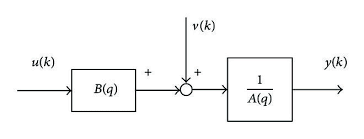

### Stampa dei grafici

FigNum = 9;
figure(FigNum)
clf

Queste righe impostano il numero del grafico (`FigNum`) e creano una nuova figura vuota con quel numero. La funzione `clf` serve a cancellare il contenuto della figura se era già presente.

f = [0:N/2]/N;                            % frequencies for plot

Questa riga calcola le frequenze corrispondenti alle **DFT lines** per il tracciamento del grafico. Viene creato un vettore `f` che rappresenta le frequenze normalizzate da 0 a N/2, divise per N.

In particolare, **le "DFT lines" si riferiscono alle frequenze specifiche a cui viene valutata la risposta in frequenza di un sistema utilizzando la Trasformata di Fourier Discreta (DFT)**.

Nel codice, il vettore `Lines` è stato definito come un insieme di frequenze selezionate per il tracciamento del grafico. Queste frequenze vengono calcolate utilizzando la variabile `N`, che rappresenta il numero di punti dati nel segnale, e vengono definite come un intervallo di frequenze da *0,04N a 0,08N* con un passo di 1. Ad esempio, se `N` è 5000, l'intervallo di frequenze corrisponderà a [200, 201, 202, ..., 400].

[GEst] = freqz(bEst, aEst, 2*pi*f);         % estimated transfer function
G0 = freqz(b0, a0, 2*pi*f);                 % exact transfer function

Queste righe calcolano le risposte in frequenza dei modelli stimati e del sistema esatto. **Utilizzando la funzione **`freqz`**, vengono calcolate le risposte in frequenza** `GEst` del modello stimato (con coefficienti `bEst` e `aEst`) e `G0` del sistema esatto (con coefficienti `b0` e `a0`).

fpref = [0:0.001:0.2]; 
Gpref = freqz(bf, af, 2*pi*fpref);  % G prefilter

Queste righe calcolano la risposta in frequenza del prefiltro (avente coefficienti `bf` e `af`) nel range di frequenza specificato. Viene creato un vettore `fpref` che rappresenta le frequenze normalizzate da 0 a 0.2, con un passo di 0.001, e la funzione `freqz` viene utilizzata per calcolare la risposta in frequenza `Gpref` del prefiltro.

plot(f, db(GEst), 'k', f(Lines), db(GEst(Lines)), 'r', f, db(G0), 'b',...
     f, db(G0-GEst), '--k', f(Lines), db(G0(Lines)-GEst(Lines)), '--r', fpref, db(Gpref), 'b')

% legend('f vs db(GEst)','f(Lines) vs db(GEst(Lines))','f vs db(G0)',...
%        'f vs db(G0-GEst)', 'f(Lines) vs db(G0(Lines)-GEst(Lines))', 'fpref vs db(Gpref)')

legend('f.r. Estimated','b.f.r. Estimated','f.r. True', 'f.r. True-Estimated', 'b.f.r. True-Estimated', 'f.r. Prefilter')

Questo blocco di codice crea il grafico delle risposte in frequenza. Vengono tracciati i seguenti grafici:

- `f` vs `db(GEst)`: risposta in frequenza del modello stimato.

- `f(Lines)` vs `db(GEst(Lines))`: risposta in frequenza del modello stimato solo per le frequenze specificate in `Lines`.

- `f` vs `db(G0)`: risposta in frequenza del sistema esatto.

- `f` vs `db(G0-GEst)`: differenza tra la risposta in frequenza del sistema esatto e quella del modello stimato.

- `f(Lines)` vs `db(G0(Lines)-GEst(Lines))`: differenza tra la risposta in frequenza del sistema esatto e quella del modello stimato solo per le frequenze specificate in `Lines`.

- `fpref` vs `db(Gpref)`: risposta in frequenza del prefiltro.

axis([0 0.2 -40 5])
% xlim([0.000 0.200])
% ylim([-40.0 5.0])

Queste righe impostano i limiti dell'asse x da 0 a 0.2 e i limiti dell'asse y da -40 a 5 nel grafico.

Le righe seguenti, invece, impostano alcune proprietà del grafico come la dimensione del carattere, le etichette degli assi, il colore dei tracciati e lo spessore dei tracciati.

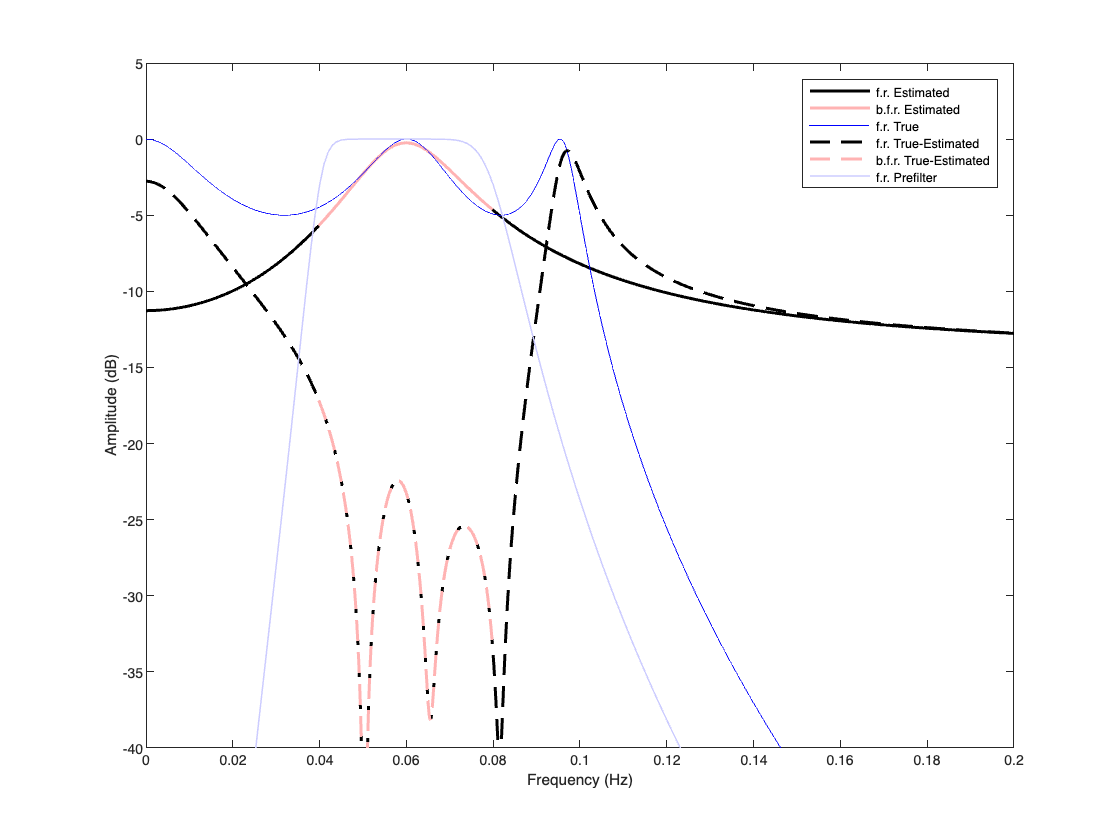

DG_SetFontSize(7)
ylabel('Amplitude (dB)')
xlabel('Frequency (Hz)')
DG_SetTraceTint(30,2,FigNum,1)
DG_SetTraceTint(30,5,FigNum,1)
DG_SetTraceTint(20,6,FigNum,1)
DG_SetTraceWidth(1.5,'*',FigNum,1)
DG_SetTraceWidth(0.5,3,FigNum,1)
DG_SetTraceWidth(0.75,6,FigNum,1)

Dove: 

- **f.r.** -> **Frequency Response** 

- **b.f.r.** -> **Bounded Frequency Response**.

### Esportazione grafici in formato PDF

% Export the plot
% DG_Init4PDF(gcf, 6);        % fixing the size, half standard height
% DG_MakePDF('FigArxModErrBPTDG0Gest.pdf', gcf);

Queste righe mostrano il codice commentato per esportare il grafico in un file PDF. Le funzioni `DG_Init4PDF` e `DG_MakePDF` vengono utilizzate per inizializzare le impostazioni del file PDF e creare effettivamente il file.

## Conclusioni

Sono ancora visibili errori di modello, l'ordine del modello è ancora troppo basso per coprire l'intera complessità del modello reale, il modello identificato è diverso da G0. Tuttavia, nella banda di frequenza selezionata dall'utente (la banda passante del prefiltro Butterworth), l'errore del modello è molto più ridotto. Al di fuori di questa banda, gli errori sono maggiori, perché si utilizza un modello ancora più semplice di ordine 2 invece che di ordine 4. Questo dimostra che l'utente può fortemente influenzare il modello e il comportamento degli errori. 

L'utente può bilanciare la complessità del modello, gli errori del modello e la sensibilità al rumore. Utilizzando un prefiltro, è possibile modellare gli errori del modello, mantenendoli piccoli in una banda di frequenza definita dall'utente.

### Appendice I - Filtro di Chebyshev

L'obiettivo principale di un filtro di Chebyshev è quello di ottenere una risposta in frequenza con una caratteristica di passaggio o di attenuazione specifica. A differenza di altri filtri, come il filtro di Butterworth, il filtro di Chebyshev permette di avere una risposta in frequenza più selettiva e una maggiore pendenza nell'intervallo di transizione tra la banda di passaggio e la banda di attenuazione.

Ci sono due tipi principali di filtri di Chebyshev: il filtro di Chebyshev tipo I e il filtro di Chebyshev tipo II.

- Filtro di Chebyshev tipo I: Questo filtro presenta una risposta in frequenza con una caratteristica di passaggio irregolare ma con una rapida caduta nell'intervallo di attenuazione. Ciò significa che le frequenze nella banda di passaggio saranno accettate senza attenuazione significativa, ma le frequenze al di fuori della banda di passaggio saranno fortemente attenuate. **La caratteristica di passaggio può avere delle risonanze o picchi che possono essere desiderabili in alcune applicazioni e indesiderabili in altre.**

- Filtro di Chebyshev tipo II: Questo filtro presenta una risposta in frequenza con una caratteristica di attenuazione irregolare, ma con una rapida caduta nell'intervallo di passaggio. Ciò significa che le frequenze nella banda di attenuazione saranno fortemente attenuate, mentre le frequenze nella banda di passaggio saranno accettate senza attenuazione significativa. A differenza del filtro di tipo I, **il filtro di tipo II non ha picchi o risonanze nella banda di passaggio.**

Entrambi i tipi di filtri di Chebyshev hanno un parametro aggiuntivo chiamato ordine del filtro, che determina la pendenza della risposta in frequenza. Un ordine maggiore produce una pendenza più ripida, ma può richiedere più risorse computazionali per implementare il filtro.

I filtri di Chebyshev sono ampiamente utilizzati in una varietà di applicazioni, come l'elaborazione del segnale, le telecomunicazioni e l'elettronica. Sono spesso utilizzati quando è necessaria una selettività elevata o una risposta in frequenza personalizzata.

### Appendice II - Filtro di Butterworth

Un filtro di Butterworth è un filtro passa-basso, passa-alto, passa-banda o taglia-banda, il cui obiettivo è quello di attenuare o ridurre la potenza di alcune frequenze del segnale di ingresso, lasciando passare solo quelle frequenze desiderate.

Ciò viene ottenuto modificando l'ampiezza del segnale di ingresso alle diverse frequenze utilizzando una funzione matematica chiamata risposta in frequenza. La risposta in frequenza del filtro di Butterworth è caratterizzata da una curva di attenuazione regolare e senza oscillazioni, che lo rende particolarmente utile in molte applicazioni.

La caratteristica principale di un filtro di Butterworth è la sua risposta piatta nella banda passante, il che significa che l'attenuazione delle frequenze all'interno di questa banda è uniforme. In altre parole, il filtro non introduce distorsioni o variazioni nella forma d'onda dei segnali che si trovano all'interno della banda passante.

Ciò è ottenuto utilizzando una funzione di trasferimento chiamata funzione di Butterworth, che è basata su polinomi razionali. Il grado del polinomio determina il comportamento del filtro e il numero di poli del polinomio determina il numero di sezioni del filtro, noto anche come ordine del filtro.

Un filtro di Butterworth può essere progettato per avere diverse caratteristiche di attenuazione e pendenza nella regione di transizione tra la banda passante e la banda di attenuazione. Ciò significa che può essere realizzato con diverse specifiche per adattarsi alle esigenze dell'applicazione. Ad esempio, un filtro di Butterworth di ordine elevato avrà una pendenza di attenuazione più ripida nella regione di transizione.

In conclusione, un filtro di Butterworth è un tipo di filtro che viene utilizzato per modificare l'ampiezza delle diverse frequenze di un segnale, attenuando quelle indesiderate. È apprezzato per la sua risposta in frequenza regolare e senza oscillazioni, che lo rende utile in molte applicazioni, come l'elaborazione audio, la comunicazione wireless, l'elaborazione dei segnali biomedici e altro ancora.

### Appendice III - Confronto tra Filtro di Chebyshev e Filtro di Butterworth

I filtri di Chebyshev e i filtri di Butterworth sono due tipi di filtri che vengono utilizzati in elettronica e telecomunicazioni per la progettazione di sistemi di filtraggio. Ecco le principali differenze tra i due:

- Risposta in frequenza: Un filtro di Chebyshev ha una risposta in frequenza selettiva, che significa che può presentare un'attenuazione più ripida nella banda di transizione (la regione tra la banda passante e la banda di stop) rispetto a un filtro di Butterworth. D'altra parte, un filtro di Butterworth ha una risposta in frequenza più piatta nella banda passante, ma ha un'attenuazione più lenta nella banda di transizione rispetto a un filtro di Chebyshev.

- Ondulazione: Un filtro di Chebyshev introduce ondulazioni nell'intervallo di passaggio, che sono deviazioni dalla risposta ideale piatta. Queste ondulazioni possono essere controllate e specificate dall'utente in base alle proprie esigenze di progettazione. Un filtro di Butterworth, al contrario, non introduce ondulazioni nell'intervallo di passaggio ed è caratterizzato da una risposta più uniforme.

- Ordine del filtro: Il filtro di Chebyshev può raggiungere un'attenuazione più elevata rispetto a un filtro di Butterworth dello stesso ordine nella banda di stop. Ciò significa che per ottenere la stessa attenuazione nella banda di stop, il filtro di Chebyshev può richiedere un ordine inferiore rispetto a un filtro di Butterworth. Tuttavia, questo vantaggio viene a scapito di un'onda di passaggio meno piatta.

- Implementazione pratica: I filtri di Butterworth sono spesso preferiti quando la priorità è una risposta in frequenza più uniforme e una semplice implementazione pratica. Sono filtri facilmente realizzabili e hanno una fase lineare in tutta la banda di passaggio. I filtri di Chebyshev, d'altra parte, possono richiedere componenti aggiuntivi, come induttori o condensatori aggiuntivi, per raggiungere le specifiche desiderate. Possono anche avere una fase non lineare nella banda di passaggio.

La scelta tra un filtro di Chebyshev e un filtro di Butterworth dipende dalle specifiche del progetto e dai requisiti di attenuazione, selettività e ondulazione nella banda di passaggio e nella banda di stop.